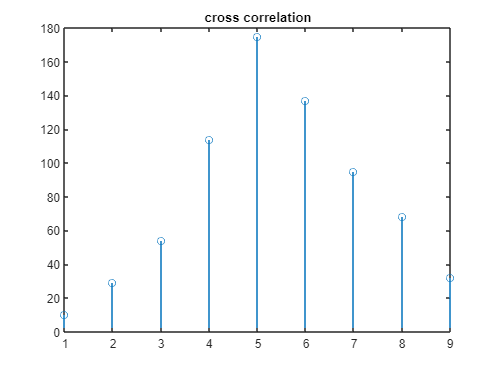

a = [1, 2 ,3,7 ,8];
b= [4 5 6,9,10];
cv2= xcorr(a,b);
b = fliplr(b);
n=length(a);
m= length(b);
cv= zeros(1,n+m-1);

for i=1:m
    for j=1:n
        cv(i+j-1) =cv(i+j-1)+ b(i)*a(j);
    end
end


stem(cv);
title("cross correlation")

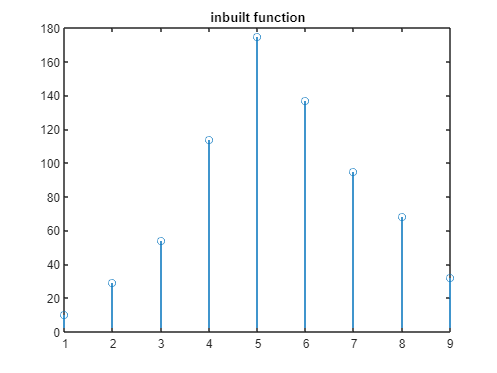

stem(cv2);
title("inbuilt function")

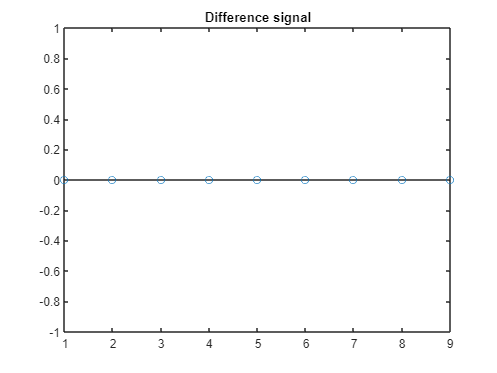

x =    -6.2832   -6.1832   -6.0832   -5.9832   -5.8832   -5.7832   -5.6832   -5.5832   -5.4832   -5.3832   -5.2832   -5.1832   -5.0832   -4.9832   -4.8832   -4.7832   -4.6832   -4.5832   -4.4832   -4.3832   -4.2832   -4.1832   -4.0832   -3.9832   -3.8832   -3.7832   -3.6832   -3.5832   -3.4832   -3.3832   -3.2832   -3.1832   -3.0832   -2.9832   -2.8832   -2.7832   -2.6832   -2.5832   -2.4832   -2.3832   -2.2832   -2.1832   -2.0832   -1.9832   -1.8832   -1.7832   -1.6832   -1.5832   -1.4832   -1.3832


y =     0.0000    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


a =    -0.0663   -0.1656   -0.2632   -0.3582   -0.4496   -0.5366   -0.6181   -0.6935   -0.7620   -0.8228   -0.8755   -0.9193   -0.9540   -0.9792   -0.9946   -1.0000   -0.9954   -0.9809   -0.9566   -0.9228   -0.8797   -0.8278   -0.7677   -0.6999   -0.6251   -0.5440   -0.4575   -0.3665   -0.2718   -0.1743   -0.0752    0.0248    0.1245    0.2229    0.3191    0.4121    0.5010    0.5849    0.6630    0.7344    0.7985    0.8546    0.9022    0.9407    0.9699    0.9894    0.9989    0.9985    0.9882    0.9679


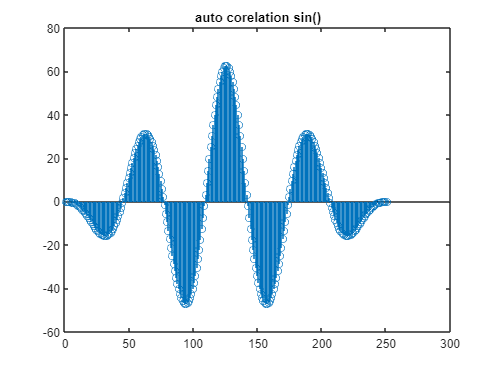

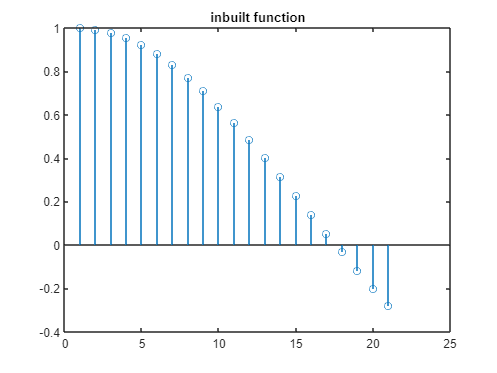

diff=round(cv-cv2);
stem(diff);
title('Difference signal');